# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 18-Jul-2020 18:08:55

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("trainingSetup_2020_07_18__18_08_53.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("imgLineaBolaDonut","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

## Augmentation Settings

imageAugmenter = imageDataAugmenter(...
    "RandYReflection",true);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([50 50 1],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([50 50 1],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",10,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([50 50 1],"Name","imageinput")
    averagePooling2dLayer([3 3],"Name","avgpool2d","Padding","same","Stride",[3 3])
    convolution2dLayer([3 3],10,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([3 3],"Name","maxpool","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    fullyConnectedLayer(3,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:02 |       30.47% |       51.76% |       1.5208 |       1.8694 |          0.0100 |


|      10 |          10 |       00:00:05 |       77.34% |       81.18% |       0.4778 |       0.5962 |          0.0100 |


|      20 |          20 |       00:00:07 |       96.09% |       96.47% |       0.0740 |       0.1864 |          0.0100 |


|      30 |          30 |       00:00:09 |      100.00% |       98.82% |       0.0039 |       0.1034 |          0.0100 |


|======================================================================================================================|


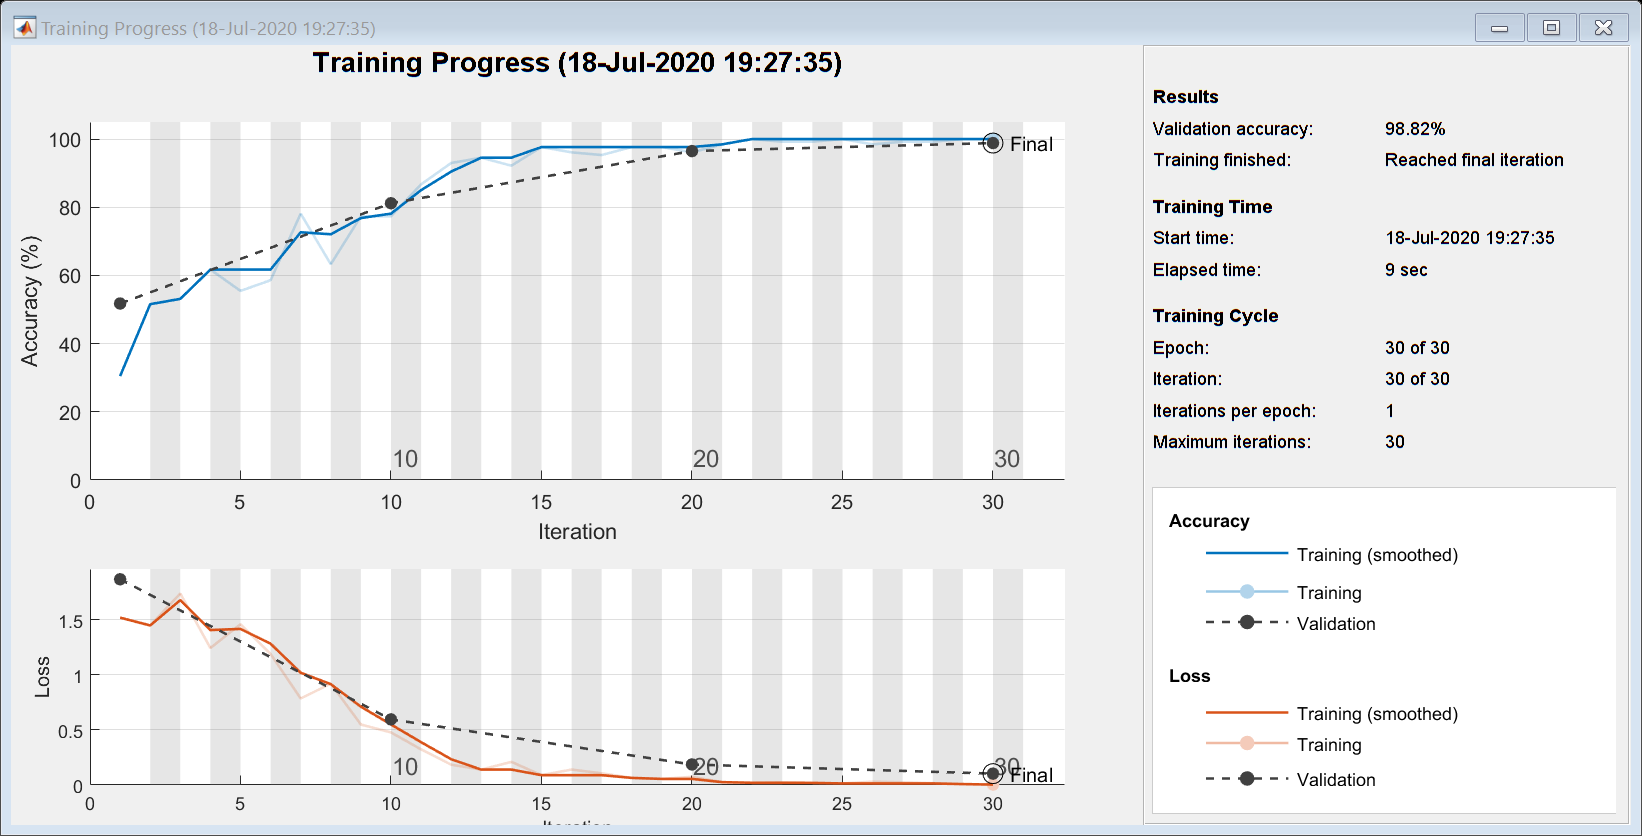

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);

## Guardar resultados

save LineaBolaDonut_deep net traininfo augimdsTrain augimdsValidation

